syms  Ms Me Mi Hs He Hi Hr Hit

lambda = 1881; beta_m = 0.134; mu_m = 0.196; theta_m = 0.58;
mu_h = 4e-4; beta_h = 1.717; theta_h =0.79; gamma_h = 1.75;

load('DataBello_full.mat');

Hit0 = DataBello.cases(519); Hi0 = DataBello.cases(519);
Me0 = 44.6; Hr0 = 81439.356; Hs0 = 318001.356;
He0 = 18; Ms0 = 1200000; Mi0 = 0;

H=Hs+He+Hi+Hr;
M=Ms+Me+Mi;

ode1 =  lambda - beta_m*Hi*Ms/H - (mu_m)*Ms;
ode2 =  beta_m*Hi*Ms/H - (theta_m+mu_m)*Me;
ode3 =  theta_m*Me - mu_m*Mi;
ode4 = -beta_h*Mi*Hs/M + (He+Hi+Hr)*mu_h;
ode5 =  beta_h*Mi*Hs/M - (theta_h+mu_h)*He;
ode6 = theta_h*He - (gamma_h+mu_h)*Hi;
ode7 =  gamma_h*Hi - mu_h*Hr;
ode8 =  theta_h*He;


vars=[Hit Hi Me Hr Hs He Ms Mi];
odes= [ode8; ode6; ode2; ode7; ode4; ode5; ode1; ode3];
opts = odeset('NonNegative',1:8); 


ydata=DataBello.cases(519:581)';
xdata=linspace(0,length(ydata)-1,length(ydata));
ydata2=ydata;
for i=1:length(ydata)
ydata2(i)=sum(ydata(1:i));
end


J = jacobian(odes, vars)

$$J = \begin{array}{l} \left(\begin{array}{cccccccc} 0 & 0 & 0 & 0 & 0 & \frac{79}{100} & 0 & 0\\ 0 & -\frac{1094}{625} & 0 & 0 & 0 & \frac{79}{100} & 0 & 0\\ 0 & \frac{67\,\mathrm{Ms}}{\sigma_{3}}-\sigma_{1} & -\frac{97}{125} & -\sigma_{1} & -\sigma_{1} & -\sigma_{1} & \frac{67\,\mathrm{Hi}}{\sigma_{3}} & 0\\ 0 & \frac{7}{4} & 0 & -\frac{1}{2500} & 0 & 0 & 0 & 0\\ 0 & \frac{1}{2500} & \sigma_{2} & \frac{1}{2500} & -\frac{1717\,\mathrm{Mi}}{\sigma_{4}} & \frac{1}{2500} & \sigma_{2} & \sigma_{2}-\frac{1717\,\mathrm{Hs}}{\sigma_{4}}\\ 0 & 0 & -\sigma_{2} & 0 & \frac{1717\,\mathrm{Mi}}{\sigma_{4}} & -\frac{494}{625} & -\sigma_{2} & \frac{1717\,\mathrm{Hs}}{\sigma_{4}}-\sigma_{2}\\ 0 & \sigma_{1}-\frac{67\,\mathrm{Ms}}{\sigma_{3}} & 0 & \sigma_{1} & \sigma_{1} & \sigma_{1} & -\frac{67\,\mathrm{Hi}}{\sigma_{3}}-\frac{49}{250} & 0\\ 0 & 0 & \frac{29}{50} & 0 & 0 & 0 & 0 & -\frac{49}{250} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{67\,\mathrm{Hi}\,\mathrm{Ms}}{500\,{\left(\mathrm{He}+\mathrm{Hi}+\mathrm{Hr}+\mathrm{Hs}\right)}^{2}}\\ \sigma_{2}=\frac{1717\,\mathrm{Hs}\,\mathrm{Mi}}{1000\,{\left(\mathrm{Me}+\mathrm{Mi}+\mathrm{Ms}\right)}^{2}}\\ \sigma_{3}=500\,\left(\mathrm{He}+\mathrm{Hi}+\mathrm{Hr}+\mathrm{Hs}\right)\\ \sigma_{4}=1000\,\left(\mathrm{Me}+\mathrm{Mi}+\mathrm{Ms}\right) \end{array}$$

syms T
A = eye(8) + J*T

$$A = \begin{array}{l} \left(\begin{array}{cccccccc} 1 & 0 & 0 & 0 & 0 & \frac{79\,T}{100} & 0 & 0\\ 0 & 1-\frac{1094\,T}{625} & 0 & 0 & 0 & \frac{79\,T}{100} & 0 & 0\\ 0 & \sigma_{2} & 1-\frac{97\,T}{125} & -\sigma_{1} & -\sigma_{1} & -\sigma_{1} & \frac{67\,\mathrm{Hi}\,T}{\sigma_{6}} & 0\\ 0 & \frac{7\,T}{4} & 0 & 1-\frac{T}{2500} & 0 & 0 & 0 & 0\\ 0 & \frac{T}{2500} & \sigma_{3} & \frac{T}{2500} & 1-\sigma_{5} & \frac{T}{2500} & \sigma_{3} & -\sigma_{4}\\ 0 & 0 & -\sigma_{3} & 0 & \sigma_{5} & 1-\frac{494\,T}{625} & -\sigma_{3} & \sigma_{4}\\ 0 & -\sigma_{2} & 0 & \sigma_{1} & \sigma_{1} & \sigma_{1} & 1-T\,\left(\frac{67\,\mathrm{Hi}}{\sigma_{6}}+\frac{49}{250}\right) & 0\\ 0 & 0 & \frac{29\,T}{50} & 0 & 0 & 0 & 0 & 1-\frac{49\,T}{250} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{67\,\mathrm{Hi}\,\mathrm{Ms}\,T}{\sigma_{7}}\\ \sigma_{2}=T\,\left(\frac{67\,\mathrm{Ms}}{\sigma_{6}}-\frac{67\,\mathrm{Hi}\,\mathrm{Ms}}{\sigma_{7}}\right)\\ \sigma_{3}=\frac{1717\,\mathrm{Hs}\,\mathrm{Mi}\,T}{\sigma_{8}}\\ \sigma_{4}=T\,\left(\frac{1717\,\mathrm{Hs}}{\sigma_{9}}-\frac{1717\,\mathrm{Hs}\,\mathrm{Mi}}{\sigma_{8}}\right)\\ \sigma_{5}=\frac{1717\,\mathrm{Mi}\,T}{\sigma_{9}}\\ \sigma_{6}=500\,\left(\mathrm{He}+\mathrm{Hi}+\mathrm{Hr}+\mathrm{Hs}\right)\\ \sigma_{7}=500\,{\left(\mathrm{He}+\mathrm{Hi}+\mathrm{Hr}+\mathrm{Hs}\right)}^{2}\\ \sigma_{8}=1000\,{\left(\mathrm{Me}+\mathrm{Mi}+\mathrm{Ms}\right)}^{2}\\ \sigma_{9}=1000\,\left(\mathrm{Me}+\mathrm{Mi}+\mathrm{Ms}\right) \end{array}$$

A= matlabFunction(A)

A = function_handle with value:
    @(He,Hi,Hr,Hs,Me,Mi,Ms,T)reshape([1.0,0.0,0.0,0.0,0.0,0.0,0.0,0.0,0.0,T.*(-1.7504)+1.0,T.*((Ms.*(6.7e+1./5.0e+2))./(He+Hi+Hr+Hs)-Hi.*Ms.*1.0./(He+Hi+Hr+Hs).^2.*(6.7e+1./5.0e+2)),T.*(7.0./4.0),T./2.5e+3,0.0,-T.*((Ms.*(6.7e+1./5.0e+2))./(He+Hi+Hr+Hs)-Hi.*Ms.*1.0./(He+Hi+Hr+Hs).^2.*(6.7e+1./5.0e+2)),0.0,0.0,0.0,T.*(-9.7e+1./1.25e+2)+1.0,0.0,Hs.*Mi.*T.*1.0./(Me+Mi+Ms).^2.*1.717,Hs.*Mi.*T.*1.0./(Me+Mi+Ms).^2.*(-1.717),0.0,T.*(2.9e+1./5.0e+1),0.0,0.0,Hi.*Ms.*T.*1.0./(He+Hi+Hr+Hs).^2.*(-6.7e+1./5.0e+2),T.*(-4.0e-4)+1.0,T./2.5e+3,0.0,Hi.*Ms.*T.*1.0./(He+Hi+Hr+Hs).^2.*(6.7e+1./5.0e+2),0.0,0.0,0.0,Hi.*Ms.*T.*1.0./(He+Hi+Hr+Hs).^2.*(-6.7e+1./5.0e+2),0.0,(Mi.*T.*(-1.717))./(Me+Mi+Ms)+1.0,(Mi.*T.*1.717)./(Me+Mi+Ms),Hi.*Ms.*T.*1.0./(He+Hi+Hr+Hs).^2.*(6.7e+1./5.0e+2),0.0,T.*(7.9e+1./1.0e+2),T.*(7.9e+1./1.0e+2),Hi.*Ms.*T.*1.0./(He+Hi+Hr+Hs).^2.*(-6.7e+1./5.0e+2),0.0,T./2.5e+3,T.*(-4.94e+2./6.25e+2)+1.0,Hi.*Ms.*T.*1.0./(He+Hi+Hr+Hs).^2.*(6.7e+1./5.0e+2),0.0,0.0,0.0,(

Ts = 1; % tiempo de muestreo T.
tiempo = 519:Ts:581; % periodo de tiempo a usar.
x0= [Hit0 Hi0 Me0 Hr0 Hs0 He0 Ms0 Mi0]; % Condición inicial
odes= matlabFunction(odes)

odes = function_handle with value:
    @(He,Hi,Hr,Hs,Me,Mi,Ms)[He.*(7.9e+1./1.0e+2);He.*(7.9e+1./1.0e+2)-Hi.*1.7504;Me.*(-9.7e+1./1.25e+2)+(Hi.*Ms.*(6.7e+1./5.0e+2))./(He+Hi+Hr+Hs);Hi.*(7.0./4.0)-Hr./2.5e+3;He./2.5e+3+Hi./2.5e+3+Hr./2.5e+3-(Hs.*Mi.*1.717)./(Me+Mi+Ms);He.*(-4.94e+2./6.25e+2)+(Hs.*Mi.*1.717)./(Me+Mi+Ms);Ms.*(-4.9e+1./2.5e+2)-(Hi.*Ms.*(6.7e+1./5.0e+2))./(He+Hi+Hr+Hs)+1.881e+3;Me.*(2.9e+1./5.0e+1)-Mi.*(4.9e+1./2.5e+2)]


y= ydata;
M = 0.01*eye(8); N = 0.5; P0 = M;x0= [Hit0 Hi0 Me0 Hr0 Hs0 He0 Ms0 Mi0]'; Ts = 0.1;
% Parámetros conocidos:
C=[0 1 0 0 0 0 0 0];
n = length(y); x_est = zeros(n,8); P_trace = zeros(n,1); K_norm = zeros(n,1);
x_act = x0; P_act = P0;
for k = 1:n
    A_ = A(x_act(6),x_act(2),x_act(4),x_act(5),x_act(3),x_act(8),x_act(7),Ts);
    % Predicción:

    H_=x_act(5)+ x_act(6)+x_act(2)+x_act(4);
    M_=x_act(7)+x_act(3)+x_act(8);

    x_pred= [x_act(1)+ Ts*(theta_h*x_act(6));
             x_act(2)+ Ts*(theta_h*x_act(6) - (gamma_h+mu_h)*x_act(2));
             x_act(3)+ Ts*(beta_m*x_act(2)*x_act(7)/H_ - (theta_m+mu_m)*x_act(3));
             x_act(4)+ Ts*(gamma_h*x_act(2)-mu_h*x_act(4));
             x_act(5)+ Ts*(-beta_h*x_act(8)*x_act(5)/M_ + (x_act(6)+x_act(2)+x_act(4))*mu_h );
             x_act(6)+ Ts*(beta_h*x_act(8)*x_act(5)/M_ - (theta_h+mu_h)*x_act(6) );
             x_act(7)+ Ts*(lambda-beta_m*x_act(2)*x_act(7)/H_ - (mu_m)*x_act(7) );
             x_act(8)+ Ts*(theta_m*x_act(3) - mu_m*x_act(8) ) ];

    P_pred = A_*P_act*A_' + M;
    % Corrección:
    K = P_pred*C'*inv(C*P_pred*C' + N);
    x_act = x_pred + K*(y(k) - C*x_pred);
    P_act = (eye(8) - K*C)*P_pred;
    % Estimación:
    x_est(k,:) = x_act';
    % Medidas:

    P_trace(k) = trace(P_act);
    K_norm(k) = norm(K);
end

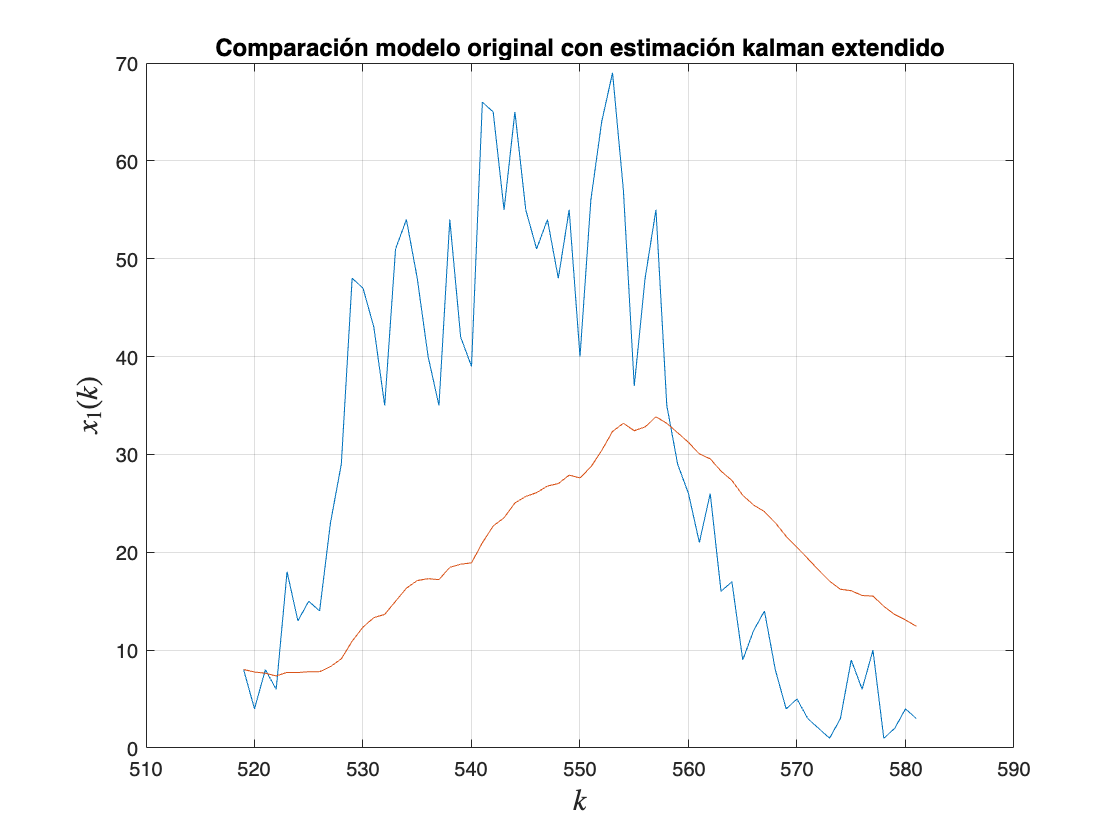

plot(tiempo,ydata,tiempo,x_est(:,2))
%legend({'Modelo original', 'Estimación Kalman Extendido'}, 'Location', 'best');
xlabel('$k$', 'Interpreter', 'Latex', 'FontSize', 15);
ylabel('$x_{1}(k)$', 'Interpreter', 'Latex', 'FontSize', 15);
title('Comparación modelo original con estimación kalman extendido', 'FontSize', 12);
grid on